% =========================================================================
% V2.0: Data-Driven Thermodynamic Regression & Parameter Estimation Engine
% =========================================================================
clc; clear; close all;

global x_exp P_exp P1_sat P2_sat

% --- 1. RAW EXPERIMENTAL DATA (Ethanol-Water at 78.15 C) ---
% Real lab data: [x1, P_exp (mmHg)]
vle_data = [
    0.000, 74.0;  0.089, 122.0; 0.197, 145.0; 0.345, 158.0;
    0.512, 164.0; 0.678, 166.5; 0.823, 167.0; 0.890, 167.3; % Azeotrope region
    0.945, 166.0; 1.000, 162.0
];

x_exp = vle_data(:,1);
P_exp = vle_data(:,2);

P1_sat = 162.0; % Pure Ethanol vapor pressure (mmHg)
P2_sat = 74.0;  % Pure Water vapor pressure (mmHg)

% --- 2. PARAMETER ESTIMATION (Non-linear Optimization) ---
% Initial guesses for [A12, A21]
initial_guess = [1.0, 1.0];

% Options for the solver
options = optimset('Display','off','TolX',1e-6);

% Run fminsearch to minimize the Objective Function (defined at the bottom)
[optimal_params, final_error] = fminsearch(@vle_objective, initial_guess, options);

A12_opt = optimal_params(1);
A21_opt = optimal_params(2);

% --- 3. GENERATE MODEL PREDICTIONS USING OPTIMIZED PARAMETERS ---
x1_model = linspace(0, 1, 100);
P_model = zeros(1, 100);
y1_model = zeros(1, 100);

for i = 1:100
    x1 = x1_model(i);
    x2 = 1 - x1;
    
    if x1 == 0
        g1 = exp(A12_opt); g2 = 1;
    elseif x1 == 1
        g1 = 1; g2 = exp(A21_opt);
    else
        g1 = exp(A12_opt * ( (A21_opt * x2) / (A12_opt * x1 + A21_opt * x2) )^2);
        g2 = exp(A21_opt * ( (A12_opt * x1) / (A12_opt * x1 + A21_opt * x2) )^2);
    end
    
    P_model(i) = x1 * g1 * P1_sat + x2 * g2 * P2_sat;
    y1_model(i) = (x1 * g1 * P1_sat) / P_model(i);
end

% Locate Azeotrope from optimized model
[max_P, az_idx] = max(P_model);

% --- 4. DISPLAY COMPUTE METRICS ---
fprintf('====================================================\n');

fprintf('   REGRESSION ENGINE RESULTS\n');

   REGRESSION ENGINE RESULTS


fprintf('====================================================\n');

fprintf('Optimized A12: %.4f | Optimized A21: %.4f\n', A12_opt, A21_opt);

Optimized A12: 1.7273 | Optimized A21: 1.1544


fprintf('Residual Sum of Squares (RSS) Error: %.4f\n', final_error);

Residual Sum of Squares (RSS) Error: 7.5010


fprintf('Predicted Azeotropic Composition: %.3f\n\n', x1_model(az_idx));

Predicted Azeotropic Composition: 0.788



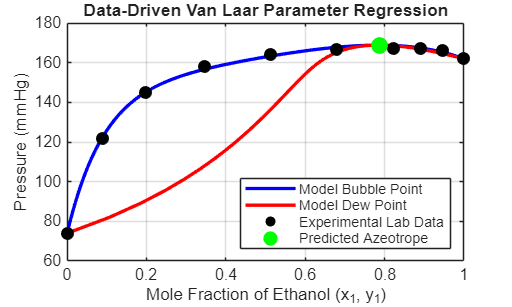


% --- 5. PLOT EXPERIMENTAL VS MODEL ---
figure('Name', 'Thermodynamic Model Fit', 'Color', 'w');
plot(x1_model, P_model, 'b-', 'LineWidth', 2); hold on;
plot(y1_model, P_model, 'r-', 'LineWidth', 2);
cool_scatter = scatter(x_exp, P_exp, 60, 'k', 'filled');
plot(x1_model(az_idx), max_P, 'g.', 'MarkerSize', 30);

xlabel('Mole Fraction of Ethanol (x_1, y_1)'); ylabel('Pressure (mmHg)');
title('Data-Driven Van Laar Parameter Regression');
legend('Model Bubble Point', 'Model Dew Point', 'Experimental Lab Data', 'Predicted Azeotrope', 'Location', 'southeast');
grid on; hold off;


% =========================================================================
% OBJECTIVE FUNCTION (To be minimized)
% =========================================================================
function SSR = vle_objective(params)
    global x_exp P_exp P1_sat P2_sat
    A12 = params(1); A21 = params(2);
    SSR = 0;
    
    for j = 1:length(x_exp)
        x1 = x_exp(j);
        x2 = 1 - x1;
        
        if x1 == 0
            g1 = exp(A12); g2 = 1;
        elseif x1 == 1
            g1 = 1; g2 = exp(A21);
        else
            g1 = exp(A12 * ( (A21 * x2) / (A12 * x1 + A21 * x2) )^2);
            g2 = exp(A21 * ( (A12 * x1) / (A12 * x1 + A21 * x2) )^2);
        end
        
        P_calc = x1 * g1 * P1_sat + x2 * g2 * P2_sat;
        SSR = SSR + (P_exp(j) - P_calc)^2; % Sum of squared residuals
    end
end